DNN

% add folder with helper function tp to path
function_folder = fullfile(pwd, 'functions');
addpath(function_folder)

cfg = struct;
cfg.subNums = [102:108, 111:114];
%cfg.subNums = 4:37;
cfg.n = length(cfg.subNums);
cfg.categories = {'bathroom', 'kitchen'};
cfg.exp_num = 2;
cfg.colormaps = load('white_zero_colormap.mat');
d = struct;
images = load_images(cfg);

Loaded image: 102_bath1_3D.png
Loaded image: 102_bath2_3D.png
Loaded image: 102_bath3_3D.png
Loaded image: 103_bath1_3D.png
Loaded image: 103_bath2_3D.png
Loaded image: 103_bath3_3D.png
Loaded image: 104_bath1_3D.png
Loaded image: 104_bath2_3D.png
Loaded image: 104_bath3_3D.png
Loaded image: 105_bath1_3D.png
Loaded image: 105_bath2_3D.png
Loaded image: 105_bath3_3D.png
Loaded image: 106_bath1_3D.png
Loaded image: 106_bath2_3D.png
Loaded image: 106_bath3_3D.png
Loaded image: 107_bath1_3D.png
Loaded image: 107_bath2_3D.png
Loaded image: 107_bath3_3D.png
Loaded image: 108_bath1_3D.png
Loaded image: 108_bath2_3D.png
Loaded image: 108_bath3_3D.png
Loaded image: 102_bath1_copy_3D.png
Loaded image: 102_bath2_copy_3D.png
Loaded image: 102_bath3_copy_3D.png
Loaded image: 103_bath1_copy_3D.png
Loaded image: 103_bath2_copy_3D.png
Loaded image: 103_bath3_copy_3D.png
Loaded image: 104_bath1_copy_3D.png
Loaded image: 104_bath2_copy_3D.png
Loaded image: 104_bath3_copy_3D.png
Loaded image: 105_bath1_c

analysis typical - layer #1 - category: bathroom
Length of labels do not match matrix dimensions


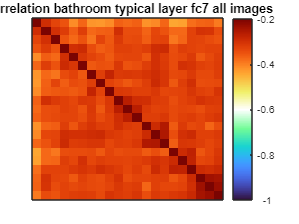

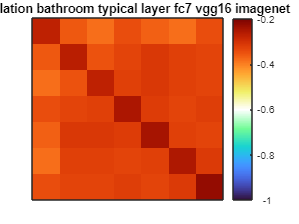

analysis typical - layer #1 - category: kitchen
Length of labels do not match matrix dimensions


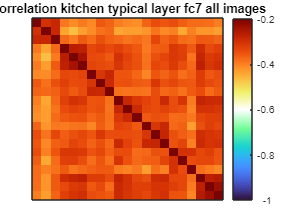

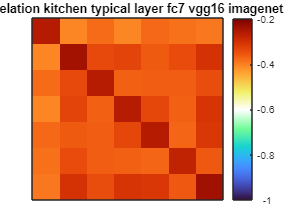


% typical images 
cfg.analysis_name = 'typical';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

analysis control - layer #1 - category: bathroom
Length of labels do not match matrix dimensions


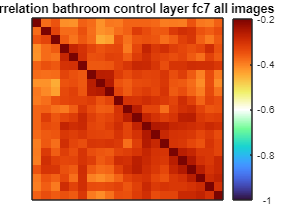

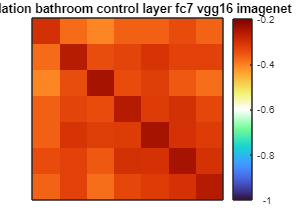

analysis control - layer #1 - category: kitchen
Length of labels do not match matrix dimensions


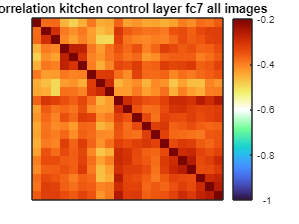

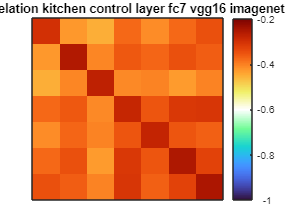


% control images 
cfg.analysis_name = 'control';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

Gaze

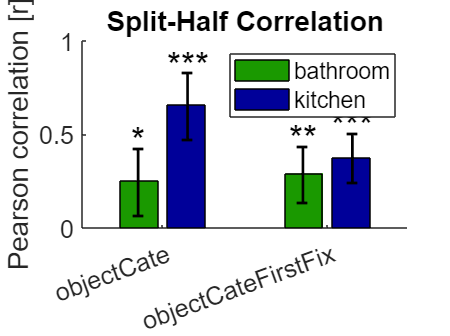

a_preprocessing(cfg)
b_detFix(cfg)
c_showFix
d_AOIfix(cfg)

d = e_makeGDM(d, cfg);
d = e_makeGDM_firstFix(d, cfg);

% split half correlation
cfg.conditions = {'objectCate', 'objectCateFirstFix'};
cfg.correlation_type = 'pearson';
d = getSpliHalfReliability(d, cfg)
plotSpliHalfReliability(d, cfg);

Get inter-subject correlation

Plotting and saving inter-subject RDM for task:ObjectDwellsMulti and bathroom


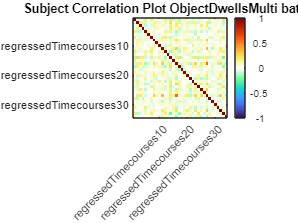

Plotting and saving inter-subject RDM for task:ObjectFixCount and bathroom


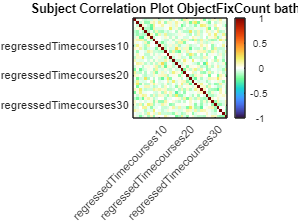

Plotting and saving inter-subject RDM for task:ObjectDwellsMultiCate and bathroom


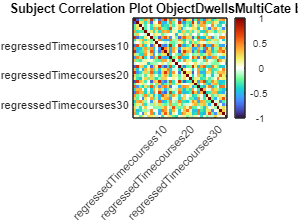

Plotting and saving inter-subject RDM for task:Objects_firstFix and bathroom


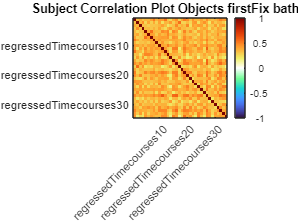

Plotting and saving inter-subject RDM for task:ObjectsCate_firstFix and bathroom


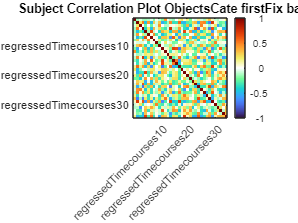

Plotting and saving inter-subject RDM for task:ObjectDwellsMulti and kitchen


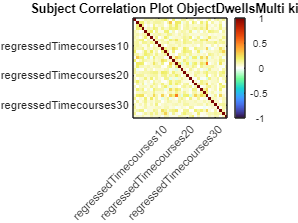

Plotting and saving inter-subject RDM for task:ObjectFixCount and kitchen


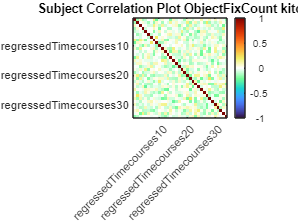

Plotting and saving inter-subject RDM for task:ObjectDwellsMultiCate and kitchen


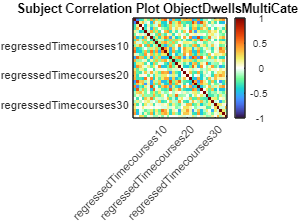

Plotting and saving inter-subject RDM for task:Objects_firstFix and kitchen


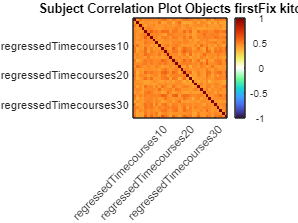

Plotting and saving inter-subject RDM for task:ObjectsCate_firstFix and kitchen


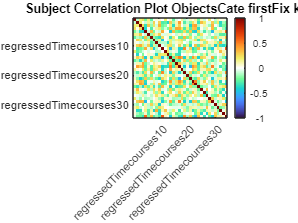

Compare categories


cfg.variables_of_interest = {};
cfg.variables_of_interest = {'ObjectDwellsMulti', 'ObjectFixCount', 'ObjectDwellsMultiCate', 'Objects_firstFix', 'ObjectsCate_firstFix'};
cfg.regressOutMean = true;
[d] = intersub_cor(d, cfg);

Compare them

 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of ObjectDwellsMultiCate bathroom is done
20% of permutations of ObjectDwellsMultiCate bathroom is done
30% of permutations of ObjectDwellsMultiCate bathroom is done
40% of permutations of ObjectDwellsMultiCate bathroom is done
50% of permutations of ObjectDwellsMultiCate bathroom is done
60% of permutations of ObjectDwellsMultiCate bathroom is done
70% of permutations of ObjectDwellsMultiCate bathroom is done
80% of permutations of ObjectDwellsMultiCate bathroom is done
90% of permutations of ObjectDwellsMultiCate bathroom is done
100% of permutations of ObjectDwellsMultiCate bathroom is done
Compare inter-subject RDM of ObjectDwellsMultiCate with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of ObjectDwellsMultiCate kitchen is done
20% of permutations of ObjectDwellsMultiCate kitchen is done
30% of permutations of ObjectDwellsM

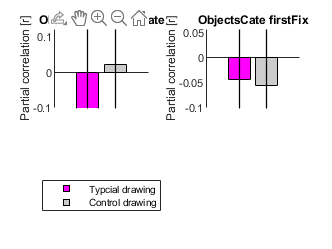

% preparation
cfg.partial_cor = true;
cfg.plot_rdm = false;
cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late','Control Images vgg16_imagenet Late'};
cfg.predictor_RDMs = {'typical_late', 'control_late'};
%cfg.tasks_of_interest = {'ObjectFixCount', 'ObjectDwellsMulti', 'Objects_firstFix', 'ObjectDwellsMultiCate', 'ObjectsCate_firstFix'};
cfg.tasks_of_interest = {'ObjectDwellsMultiCate', 'ObjectsCate_firstFix'};
cfg.dnns = {'vgg16_imagenet'};
cfg.plot_type = 'bar';
cfg.show_single_cate = false;
cfg.permutation_test = true;
cfg.n_permutations = 10000;
cfg.permutation_type = 'row_col_shuffle_pred';

cfg.partial_correlation_type = 'pearson';

d = compare_task_RDMs_to_predictor_RDMs(d, cfg);